# Generating animation in MATLAB

In this section, we will show you how to create animations using MATLAB. If you are wondering "What is MATLAB? please try "[MATLAB Onramp](https://jp.mathworks.com/learn/tutorials/matlab-onramp.html)".

If you do not know how to run this script, please read [the instructions here](matlab:open('how_to_use_livescript.mlx')).

The final animation created by this script is shown below.

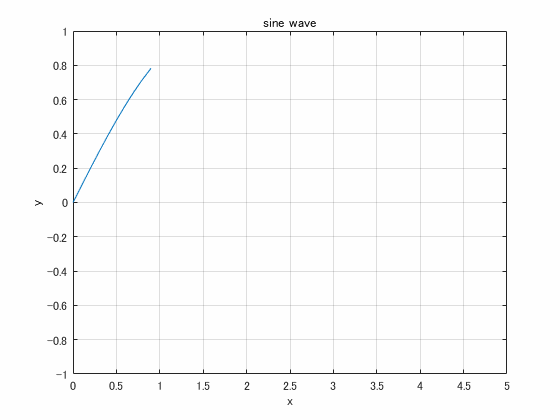

## Initialization

clear; close all; clc;

## Review of creating graph in MATLAB

Before we start creating animations in MATLAB, let's review how to create graphs in MATLAB! In this tutorial, we will visualize the following equation.


$$y = \sin(x)~~(0\leq x \leq 5)$$


### Generate data

First, we need data to be visualized. We need to generate a vector x dividing the range indicated by the above equation into 0.1 increments, and the value of y at each x. (For more details, try "[MATLAB Onramp](https://jp.mathworks.com/learn/tutorials/matlab-onramp.html)"!)

x = 0:0.1:5;
y = sin(x);

### Visualize sine wave

Next, let's visualize (x,y) created above. The [plot function](https://jp.mathworks.com/help/matlab/ref/plot.html) is used for visualization.

figure
plot(x,y);

You can also add titles, labels, and other necessary information here!

title("sine wave");
xlim([0 5]); % 0<x<5
ylim([-1 1]); % -1<y<1
xlabel("x");
ylabel("y");
grid on % Show grid

This is a review of graphing in MATLAB. We will now move on to creating animations.

## Generating animation in MATLAB

First, why do animations move?

The reason is that by displaying a series of slightly different images, it appears as if the objects in the still images are moving continuously. In other words, you can create an animation by doing the following things.

- Prepare a large number of slightly different images.

- Displaying images in sequence

Now, let's do these things.

### How to create a slightly different still image

In this case, we will create an animation in which the sine wave extends little by little. In this case, we need to prepare several images of different lengths of the sine wave. 

In this section, we will create graphs of sine waves of different lengths by modifying the already visualized graphs.

First, create a graph of a sine wave as in the previous section.

figure
p = plot(x,y);
title("sine wave");
xlim([0 5]); % 0<x<5
ylim([-1 1]); % -1<y<1
xlabel("x");
ylabel("y");
grid on

It is different in one place from the previous one! 

Here, we change to

The variable p is called "[Line Properties](https://jp.mathworks.com/help/map/ref/map.graphics.primitive.line-properties.html)". This variable include following information.

- What you draw

- How you draw

And the x- and y-axis data of the line you are drawing are stored in XData and YData. Let's try to change these two!

p.XData = x(1:10);
p.YData = y(1:10);
drawnow % Draw the figure now!!

What do you think? The display range has changed. As you can see, MATLAB allows you to change the graph even after it is created. And with drawnow, you can see the modified graph immediately after the change.

Have you noticed? You already have everything you need!

### Displaying still images in sequence

Then, how can we draw the sine waves in such a way that they grow in sequence?

Now, x and y contain the x-axis values from 0 to 5 and the corresponding sin(x) values. Then, if we gradually increase the display range from 1, the line will grow, don't you think? Then, if you display the line with [drawnow](https://jp.mathworks.com/help/matlab/ref/drawnow.html?s_tid=doc_ta) each time you change the display range, you should be able to create an animation!

Now, let's try it again with a for statement!

for i = 1:length(x)
    p.XData = x(1:i);
    p.YData = y(1:i);
    drawnow
end

What do you think? Were you able to create the animation we are aiming for?

## Bonus

You want to save your animations and show them off to everyone.

In MATLAB Live Script that you are using now, you can easily save your animation by clicking the "Export Animation" icon in the lower right corner of the figure after creating an animation using for and drewow statements.

However, it is not possible to specify the speed and quality of the animation in detail. To do so, you can use the [VideoWriter function](https://jp.mathworks.com/help/matlab/ref/videowriter.html?s_tid=doc_ta) in MATLAB. The following is a sample code (a video named "sample.mp4" is saved).

v = VideoWriter("sample.mp4",'MPEG-4');
v.Quality = 90;
v.FrameRate = 25;
open(v);
for i = 1:length(x)
    p.XData = x(1:i);
    p.YData = y(1:i);
    frame = getframe(gcf);
    writeVideo(v,frame);
end
close(v);

Let's try to make many attractive animations!

## [Return to evaluate simulation result](matlab:open('evaluate_result.mlx'))

## [Return to menu](matlab:open('workshopMenu.mlx'))